**Interpolating Salmon Egg Growth Data **

I explored the use of 2D interpolation to model the growth rates of salmon fish eggs based on environmental factors such as temperature and nutrient levels. Interpolation is a powerful tool that allows us to predict values between measured data points, providing finer insights into biological processes. By applying different interpolation methods—nearest, linear, cubic, and spline—I aimed to understand how various techniques impact the smoothness and accuracy of predictions. These methods are particularly useful for studying salmon egg growth, where data collection may be sparse or irregular.

I began by defining a coarse grid representing environmental factors like temperature and nutrient levels. Growth rates were simulated using a hypothetical formula to create variability, mimicking real-world conditions.

To refine the data, I interpolated growth rates over a finer grid using different techniques:

- **Nearest Neighbor Interpolation**: A simple method that assigns values from the closest data point.

- **Linear Interpolation**: A straightforward method that estimates values by linearly weighting nearby points.

- **Cubic Interpolation**: A smoother approach that fits cubic polynomials, capturing nonlinear trends.

- **Spline Interpolation**: The most precise method, ideal for generating smooth curves.

Each interpolation method was visualized using 3D surface plots, allowing for direct comparisons. The results demonstrated that more advanced methods like cubic and spline interpolation provided smoother transitions and better predictions, making them suitable for studying fine-scale biological variations.

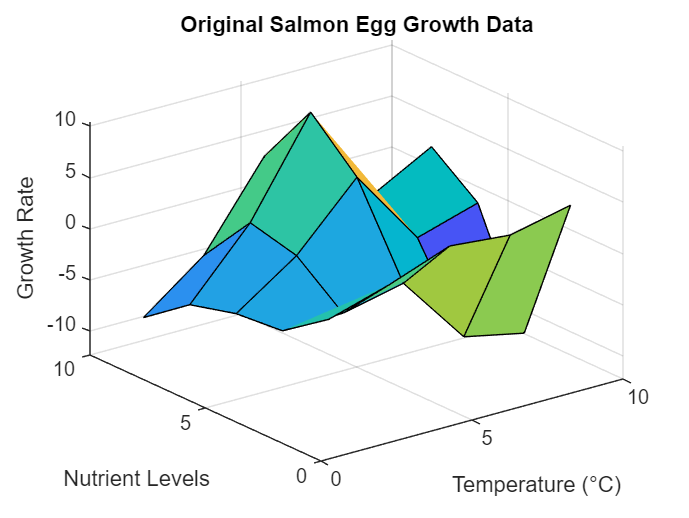

% Step 1: Initialize the growth data
[X, Y] = meshgrid(1:2:10); 
% I created a coarse grid using 'meshgrid' to represent temperature (X) and nutrient levels (Y).
% This grid represents the environmental conditions affecting salmon egg growth.

Z = X .* cos(Y) - Y .* sin(X); 
% I simulated growth rates (Z) as a function of temperature and nutrients using a hypothetical formula.
% This adds variability to mimic real-world biological data.

% Step 2: Visualize the original growth data
figure; % I created a new figure to display the original data.
surf(X, Y, Z); 
% I used 'surf' to create a 3D surface plot of the growth data for better visualization.
xlabel('Temperature (°C)'); % I labeled the x-axis to represent temperature values.
ylabel('Nutrient Levels'); % I labeled the y-axis to represent nutrient levels.
zlabel('Growth Rate'); % I labeled the z-axis to represent salmon egg growth rates.
title('Original Salmon Egg Growth Data'); % I added a title to describe the plot.
grid on; % I turned on the grid to improve the interpretability of the plot.

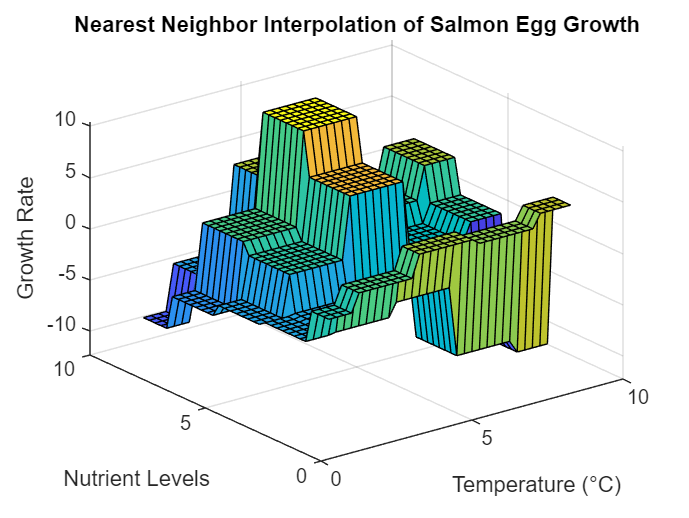


% Step 3: Set finer grid points for interpolation
[Vx, Vy] = meshgrid(1:0.25:10); 
% I created a finer grid to interpolate the data. This finer resolution helps predict growth values between the original grid points.

% Step 4: Perform nearest neighbor interpolation
Vz_nearest = interp2(X, Y, Z, Vx, Vy, 'nearest'); 
% I used 'nearest' interpolation to assign growth values based on the nearest original data point.
% This method is simple but may result in a blocky appearance in the output.

% Visualize nearest neighbor interpolation
figure; % I opened a new figure for the nearest neighbor interpolation results.
surf(Vx, Vy, Vz_nearest); 
% I plotted the interpolated data using 'surf' to observe how nearest neighbor interpolation approximates growth rates.
xlabel('Temperature (°C)'); 
ylabel('Nutrient Levels'); 
zlabel('Growth Rate'); 
title('Nearest Neighbor Interpolation of Salmon Egg Growth'); % I added a title to describe the plot.
grid on;

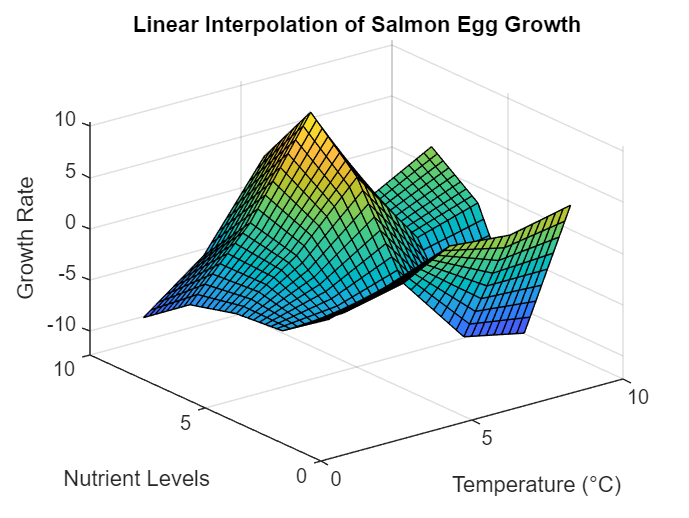


% Step 5: Perform linear interpolation
Vz_linear = interp2(X, Y, Z, Vx, Vy, 'linear'); 
% I applied 'linear' interpolation to estimate growth rates by linearly weighting nearby data points.
% This method provides smoother transitions than nearest neighbor interpolation.

% Visualize linear interpolation
figure; % I opened a new figure for linear interpolation results.
surf(Vx, Vy, Vz_linear); 
xlabel('Temperature (°C)'); 
ylabel('Nutrient Levels'); 
zlabel('Growth Rate'); 
title('Linear Interpolation of Salmon Egg Growth'); 
grid on;

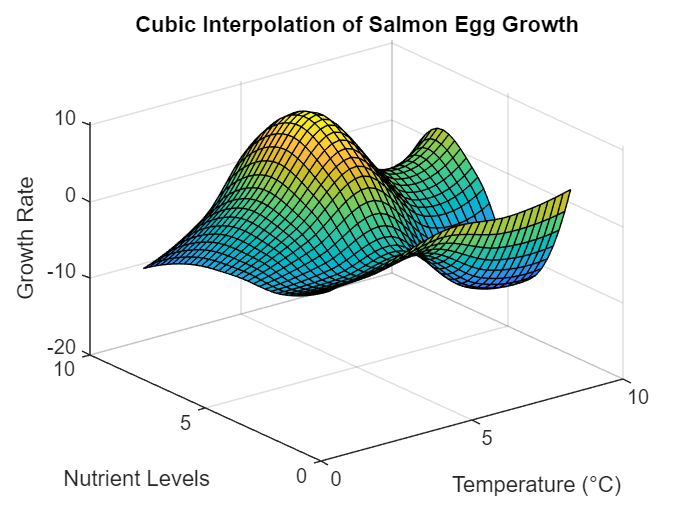


% Step 6: Perform cubic interpolation
Vz_cubic = interp2(X, Y, Z, Vx, Vy, 'cubic'); 
% I used 'cubic' interpolation to fit cubic polynomials, creating smoother and more natural transitions.
% This method is particularly effective for capturing nonlinear trends in growth data.

% Visualize cubic interpolation
figure; % I opened a new figure for cubic interpolation results.
surf(Vx, Vy, Vz_cubic); 
xlabel('Temperature (°C)'); 
ylabel('Nutrient Levels'); 
zlabel('Growth Rate'); 
title('Cubic Interpolation of Salmon Egg Growth'); 
grid on;

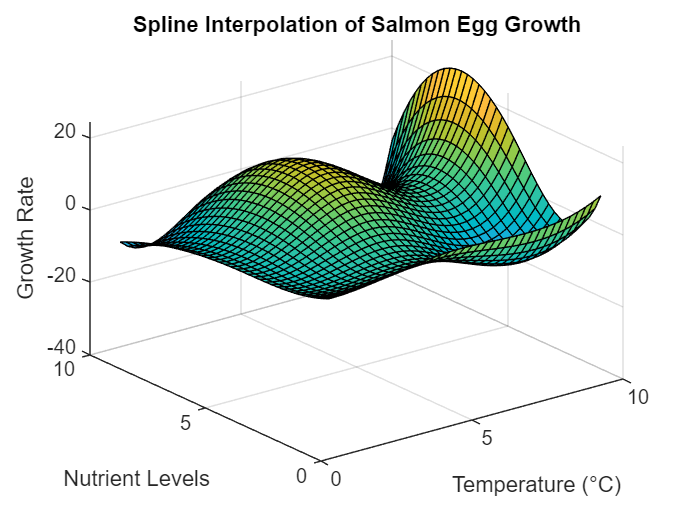


% Step 7: Perform spline interpolation
Vz_spline = interp2(X, Y, Z, Vx, Vy, 'spline'); 
% I employed 'spline' interpolation for the smoothest predictions, ideal for capturing fine details in growth patterns.

% Visualize spline interpolation
figure; % I opened a new figure for spline interpolation results.
surf(Vx, Vy, Vz_spline); 
xlabel('Temperature (°C)'); 
ylabel('Nutrient Levels'); 
zlabel('Growth Rate'); 
title('Spline Interpolation of Salmon Egg Growth'); 
grid on; 